# Figure 4G

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A068_data.mat'],'S','settings','allIF');

conditions = settings.conditions

conditions = 20×5 cell array
    {'siRIF1 DMSO DMSO'     }    {[2 3 4]}    {[2]}    {[1]}    {[71]}
    {'siControl DMSO DMSO'  }    {[4 5 6]}    {[2]}    {[1]}    {[71]}
    {'siRIF1 CDC7i DMSO'    }    {[2 3 4]}    {[3]}    {[1]}    {[71]}
    {'siControl CDC7i DMSO' }    {[4 5 6]}    {[3]}    {[1]}    {[71]}
    {'siRIF1 CDK2i DMSO'    }    {[2 3 4]}    {[4]}    {[1]}    {[71]}
    {'siControl CDK2i DMSO' }    {[4 5 6]}    {[4]}    {[1]}    {[71]}
    {'siRIF1 CDK1i DMSO'    }    {[2 3 4]}    {[5]}    {[1]}    {[71]}
    {'siControl CDK1i DMSO' }    {[4 5 6]}    {[5]}    {[1]}    {[71]}
    {'siRIF1 WEE1i DMSO'    }    {[2 3 4]}    {[6]}    {[1]}    {[71]}
    {'siControl WEE1i DMSO' }    {[4 5 6]}    {[6]}    {[1]}    {[71]}
    {'siRIF1 CDC7i CDK1i'   }    {[2 3 4]}    {[7]}    {[1]}    {[71]}
    {'siControl CDC7i CDK1i'}    {[4 5 6]}    {[7]}    {[1]}    {[71]}
    {'siRIF1 CDC7i CDK2i'   }    {[2 3 4]}    {[8]}    {[1]}    {[71]}
    {'siControl CDC7i CDK2i'}    {[4 5 6]}    {[


framesPerHr = 60/12;
 frameDrugAdded =71;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

xthresh =2e6; %x value of peak
xrange = linspace(4e6,10000); %row vector of 1000 points between x and y (all the data)
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange); %probility density plot of values from all xdata to xrange - max x of first peak
    xi_trunc = xi(xi<xthresh); %xi_trunc = all xdata <x thresh (peak of first peak)
    f_trunc = f(xi<xthresh); % f_trunc = probability density estimate for all xdata <x tresh
    [~, maxi] = max(f_trunc); %maxi = index of peak
    N_peak = xi_trunc(maxi); %peak is max of (all xdata<x thresh) which is at index maxi
    S(i).DNA_peak = N_peak;

end

4G


colors =  [.5 .5 .5 ;.1 .4 1;  .6 .9 .2;.9 .4 .2];
%background 170 - G2 signal of pMCM2
%background 130 - G2 signal of total MCM2
conds=[2 1 4 3] ;
POI_align = 1;
ally = [];
groups = [];
timeGate = [0 20];

 perc99=[];
    perc=[];
perc1=[];
     for i = 1:length(conds)
   
       ind= ~isnan(S(conds(i)).POI(:,1)) & S(conds(i)).POI_time(:,1)>= 3& S(conds(i)).POI_time(:,1)<=5;
      sum(ind)

    
        ydata = [];

         ydata(:, 1) = (((S(conds(i)).YFP2(ind))));
        ydata(:, 2) = 2*(S(conds(i)).dna(ind)/S(conds(i)).DNA_peak);
        ydata(:, 3) = (((S(conds(i)).iRFP2(ind))));
        ydata(:,4) = (ydata(:,3)./ydata(:,1));
    

           yvals = ydata(:,4);

perc99(i)=prctile(yvals,99);  
perc1(i)=prctile(yvals,1); 

 ind = ydata(:,4) > perc1(i) & ydata(:,4) <perc99(i);

 yvals = ydata(ind,4);

  
              ally = [ally; yvals];
            groups = [groups; repmat(i,size(yvals))];
            length(yvals);

  

      end

ans = 2339

ans = 1928

ans = 1934

ans = 1890

 

cols = repmat({colors(1,:),colors(2,:),colors(3,:),colors(4,:)}',1,1);
groupcol = repmat([colors([1 2 3 4 ],:)],1,1);
 figure ('units','inches','position',[0 0 6 6])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',1.5,'histOri','left','widthDiv',[2 1]);

set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',.5)
set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'pMCM2(Ser53) / MCM2'])


median_test1 =mediantest(ally(groups==1),ally(groups==2))

median_test1 = 5.1521e-62

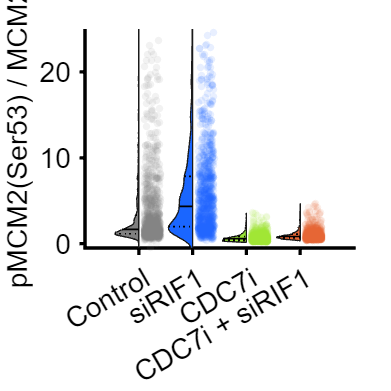


xticklabels({'Control','siRIF1','CDC7i','CDC7i + siRIF1'})
 ylim([-.5 25])
 set(gca,'linewidth',2,'fontsize',17)

hold off

 % print_pdf(['fig_4G.pdf'])